# 23 January 203

## Q4

clear;
clc;
syms q1 q2 q3 q4 real
qus = [q1 q2 q3 q4];
% important map at pag 27 slide 11

r = [q2*cos(q1) + q4*cos(q1+q3);
    q2*sin(q1)+q4*sin(q1+q3);
    q1+q3];
J = jacobian(r)

$$J = \left(\begin{array}{cccc} -q_{4}\,\sin\left(q_{1}+q_{3}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -q_{4}\,\sin\left(q_{1}+q_{3}\right) & \cos\left(q_{1}+q_{3}\right)\\ q_{4}\,\cos\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & q_{4}\,\cos\left(q_{1}+q_{3}\right) & \sin\left(q_{1}+q_{3}\right)\\ 1 & 0 & 1 & 0 \end{array}\right)$$

% singular configurations
[eq_vec] = davedet(J);
% solvable for 
% q3 = {0,pi} and q2 = 0
qs = [q1 0 0 q4];

% (I) question
% qdot ~= 0 such that rdot = 0 
% solution:
% being rdot = v then we are seeking J*qdot = 0
% so the configuration given by the null space
nullbasis = simplify(null(J))

$$nullbasis = \left(\begin{array}{c} -\frac{\sin\left(q_{3}\right)}{q_{2}}\\ -\cos\left(q_{3}\right)\\ \frac{\sin\left(q_{3}\right)}{q_{2}}\\ 1 \end{array}\right)$$

% (II) question:
% in a singular config
Js = subs(J, qus, qs)

$$Js = \left(\begin{array}{cccc} -q_{4}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & -q_{4}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ q_{4}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & q_{4}\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 1 & 0 & 1 & 0 \end{array}\right)$$

nullbasis_s = null(Js)

$$nullbasis\_s = \left(\begin{array}{cc} -1 & 0\\ 0 & -1\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

% (III) question:
% it asks for directions in which velocities are not 
% feasible in singular configuration
%
% ragionamento soluzione:
% feasible directions = image space (= range space)
% unfeasible => ortogonal complementary space to the feasible
% => apply LAW pag 581 libro: 
% N(A) = R.ort(A') and R(A) = N.ort(A')
% so we to find the directions we need to find the basis
% of the following space with the follow. reasoning:
% unfeasible = R.ort(A) (e non A' perche' ragioniamo sulle
% velocita' e non sulle forze) =>
% => N(A')
direction = simplify(null(Js'))

$$direction = \left(\begin{array}{c} \frac{\sin\left(q_{1}\right)}{q_{4}}\\ -\frac{\cos\left(q_{1}\right)}{q_{4}}\\ 1 \end{array}\right)$$

% (IV) question:
% generalized task force f0 ~= 0 statically balanced by
% joint torque tau = 0 when robot in regular config.
%
% reasoning solution:
% tau = 0 in the null space for A'
% so we are seeking a result of null different from zero
taskf = simplify(null(J'))

 
taskf =
 
Empty sym: 3-by-0
 


% empty sym 3x0 so there is no f0 ~= 0 

% (V) question:
% all the forces f that can be balanced by the zero torque
% when the robot is in singular config
%
% reasoning solution:
% tau = 0 so reason in null space. We seek all results
% of null(Js')
syms alpha real
sekt = alpha * direction

$$sekt = \left(\begin{array}{c} \frac{\alpha \,\sin\left(q_{1}\right)}{q_{4}}\\ -\frac{\alpha \,\cos\left(q_{1}\right)}{q_{4}}\\ \alpha \end{array}\right)$$

% in this way we obtain EVERY force, having the basis vector
% and a generic scalar alpha real

## Q5

clear;
clc;
syms r h real
syms s(t)

% parametrizzazione
C = [0; 0; r];
p = C + [r*sin(s);
    h*s;
    r*cos(s)];

% velocita'
p_dot = diff(p, t)  

$$p\_dot(t) = \left(\begin{array}{c} r\,\cos\left(s\left(t\right)\right)\,\frac{\partial }{\partial t}s\left(t\right)\\ h\,\frac{\partial }{\partial t}s\left(t\right)\\ -r\,\sin\left(s\left(t\right)\right)\,\frac{\partial }{\partial t}s\left(t\right) \end{array}\right)$$


psp = p_dot/diff(s,t);
pspnorm = simplify(norm(psp))

$$pspnorm(t) = \sqrt{h^{2}+{\left|r\,\cos\left(s\left(t\right)\right)\right|}^{2}+{\left|r\,\sin\left(s\left(t\right)\right)\right|}^{2}}$$


% accelerazioni
p_dbdot = diff(p_dot,t)

$$p\_dbdot(t) = \left(\begin{array}{c} r\,\cos\left(s\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)-r\,\sin\left(s\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}s\left(t\right)\right)}^{2}\\ h\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)\\ -r\,\sin\left(s\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}s\left(t\right)-r\,\cos\left(s\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}s\left(t\right)\right)}^{2} \end{array}\right)$$

% frenet frames
% t = simplify(psp/pspnorm);
tt = [r*cos(s); h; -r*sin(s)] * (1/sqrt(h^2+r^2))

$$tt(t) = \left(\begin{array}{c} \frac{r\,\cos\left(s\left(t\right)\right)}{\sqrt{h^{2}+r^{2}}}\\ \frac{h}{\sqrt{h^{2}+r^{2}}}\\ -\frac{r\,\sin\left(s\left(t\right)\right)}{\sqrt{h^{2}+r^{2}}} \end{array}\right)$$

tds = diff(t,s)

$$tds(t) = 0$$

% n = simplify(tds/norm(tds));
n = [-sin(s); 0; -cos(s)]

$$n(t) = \left(\begin{array}{c} -\sin\left(s\left(t\right)\right)\\ 0\\ -\cos\left(s\left(t\right)\right) \end{array}\right)$$

% check on FrenetFrames function work
% [tt,nn,bb, check] = FrenetFrames(p)
% probably functioning but matlab does not simplify

pdbsp = diff(psp,s);
% components
pp11t = simplify(psp' * tt)

$$pp11t(t) = \frac{h^{2}}{\sqrt{h^{2}+r^{2}}}+\frac{r^{2}\,\cos\left(\bar{s\left(t\right)}-s\left(t\right)\right)}{\sqrt{h^{2}+r^{2}}}$$

pp22t = simplify(pdbsp' * tt)

$$pp22t(t) = -\frac{r^{2}\,\sin\left(\bar{s\left(t\right)}-s\left(t\right)\right)}{\sqrt{h^{2}+r^{2}}}$$

pp1n = simplify(psp' * n)

$$pp1n(t) = r\,\sin\left(\bar{s\left(t\right)}-s\left(t\right)\right)$$

pp22n = simplify(pdbsp' * n)

$$pp22n(t) = r\,\cos\left(\bar{s\left(t\right)}-s\left(t\right)\right)$$

% note: where there is a s(t_hat) - s(t) it is equal to zero

% conditions 
p_dot_norm = simplify(norm(p_dot))

$$p\_dot\_norm(t) = \sqrt{{\left|h\,\frac{\partial }{\partial t}s\left(t\right)\right|}^{2}+{\left|r\,\cos\left(s\left(t\right)\right)\,\frac{\partial }{\partial t}s\left(t\right)\right|}^{2}+{\left|r\,\sin\left(s\left(t\right)\right)\,\frac{\partial }{\partial t}s\left(t\right)\right|}^{2}}$$

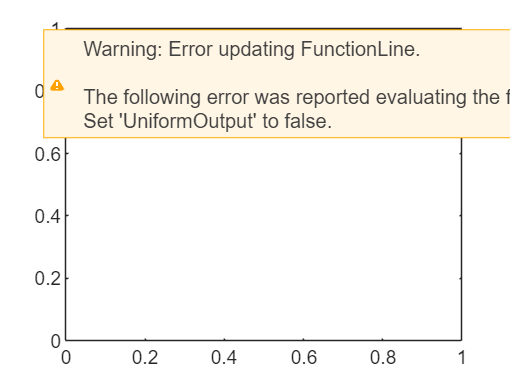

% plots
interval = [0 4.1192];
plot_function(p, t, interval)

% not functioning easy by hand